A variation on Pipeline Part 6 that checks what happens when enzyme decay is turned off in a 2d environment.

In theory, any amount of enzyme should eventually convert all cellulose into glucose.

The 'producer' here has alpha set to 0, so it's not actually producing enzyme

data file saved as dat_no_enzyme_decay.mat

%Temporary / diagnostic changes

%change amount of initial enzyme
%args.p6.v.initenzyme = args.p6.v.initenzyme * 1000

%remove enzyme decay
args.p6.v.enzdecayperhour = 0;

args.p6.v.drainatedges = false;

args.p6.v.maxcycles = 1000;
args.p6.v.timestep = 5;

args.p6.v.alpha = exp(-4);
args.p6.v.alpha = 0; %turn off enzyme production

args.p6.v.numExRxnSubsteps = 1;

args.p6.v.xdim = 5;
args.p6.v.ydim = 5;

args.p6.v.lograte = 5;

if ~exist('remcfg','var')
    load remoteconfig;
end

initenzyme = [1e-2 1e-3 1e-4 1e-5 1e-6 1e-7 1e-8 1e-9];
initenzyme = [1e-2 1e-5 1e-9];

args.p6.distances = 0;


%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(args.p6,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};

%remove the 'cheater' biomass
layout_base.models = layout_base.models(1);
layout_base.initial_pop = 0;
layout_base = setInitialPop(layout_base,'colonies',args.p6.v.initialpop,false);

layouts = cell(length(initenzyme));
for i = 1:length(initenzyme)
    layout_base = setInitialMediaInCell(layout_base,ceil(args.p6.v.xdim/2),ceil(args.p6.v.xdim/2),'enzyme[e]',initenzyme(i));
    layouts{i} = layout_base;
end
[layouts,remcfg,~] = runCometsRemotely(layouts,remcfg);

Creating Comets file batch 190408163510
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190408163510 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190408163510
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190408163510/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190408163510/* ./190408163510
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


%Run the push/execute/pull scripts here
% % system('bash C:/sync/biomes/cellulose/optima/temp/pushcomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/runremotecomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/pullcomets.sh')


%Load the results and apply to dat6nd
batchnum = remcfg.batchnum

batchnum = '190408163510'

dat6nd = part6_parseRemoteResults(layouts,batchnum);

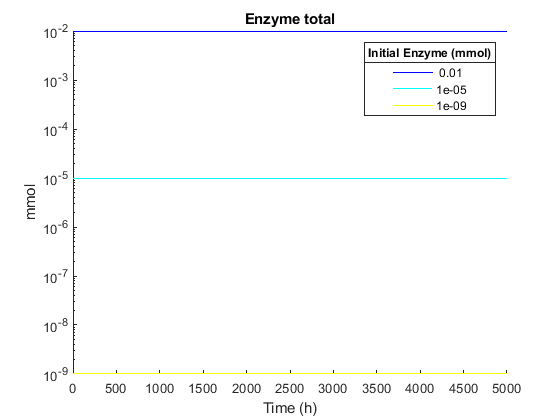

[nrows,ncols] = size(dat6nd);
colors = jet(nrows);
figure();
hold on;
for i = 1:nrows
    plot(dat6nd.t{i},dat6nd.enz_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

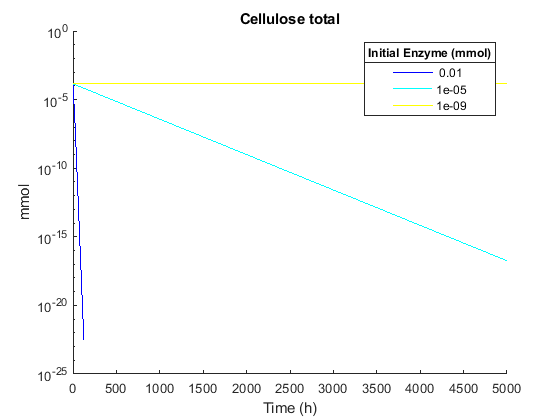


figure();
hold on;
for i = 1:nrows
    plot(dat6nd.t{i},dat6nd.cellulose_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

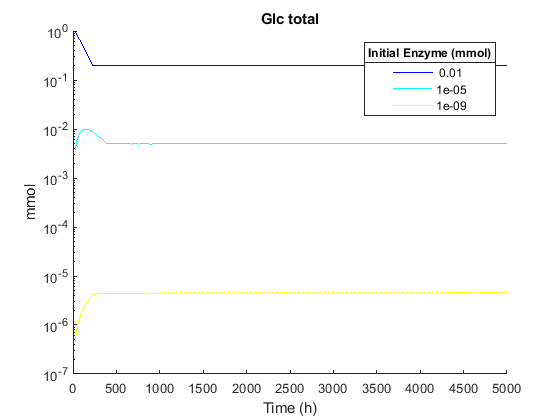


figure();
hold on;
for i = 1:nrows
    plot(dat6nd.t{i},dat6nd.glc_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

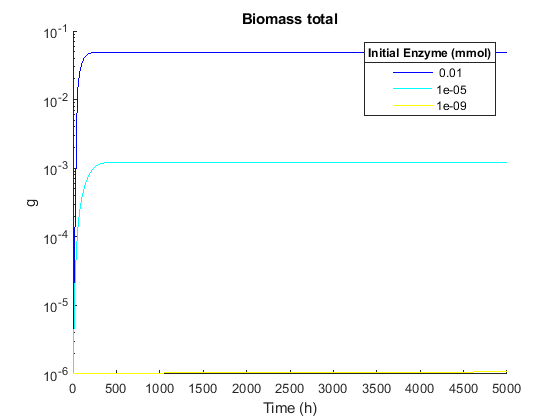


figure();
hold on;
for i = 1:nrows
    plot(dat6nd.t{i},dat6nd.producer_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('g');

% figure();
% hold on;
% for i = 1:nrows
%     plot(dat6nd.t{i}(2:end),dat6nd.glc_delta{i},'color',colors(i,:));
% end
% %set(gca,'Yscale','log');
% title('Glucose Delta');
% leg = legend(num2str(initenzyme'));
% title(leg,'Initial Enzyme (mmol)');
% xlabel('Time (h)');
% ylabel('mmol');
% 
% figure();
% hold on;
% for i = 1:nrows
%     plot(dat6nd.t{i}(2:end),dat6nd.cellulose_delta{i},'color',colors(i,:));
% end
% %set(gca,'Yscale','log');
% title('Cellulose Delta');
% leg = legend(num2str(initenzyme'));
% title(leg,'Initial Enzyme (mmol)');
% xlabel('Time (h)');
% ylabel('mmol');

hold off;

Theory: glucose floor is not the same for all samples because growth is stopping, because something other than glc is running out

Test: Increase amount of all media and compare

initenzyme = [1e-2 1e-3 1e-4];
layouts_standardmedia = layouts;

arg = args.p6;
arg.v.initO2 = args.p6.v.initO2 * 1000;
arg.v.initNH4 = args.p6.v.initNH4 * 1000;
arg.v.initCO2 = args.p6.v.initCO2 * 1000;
arg.v.initPi = args.p6.v.initPi * 1000;
arg.v.initSO4 = args.p6.v.initSO4 * 1000;
arg.v.initK = args.p6.v.initK * 1000;
arg.v.initH2O = args.p6.v.initH2O * 1000;
arg.v.initfe2 = args.p6.v.initfe2 * 1000;

%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(arg,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};
layouts_extramedia = cell(length(initenzyme));
for i = 1:length(initenzyme)
    layout_base = setInitialMediaInCell(layout_base,ceil(args.p6.v.xdim/2),ceil(args.p6.v.xdim/2),'enzyme[e]',initenzyme(i));
    layouts_extramedia{i} = layout_base;
end
[layouts_extramedia,remcfg,~] = runCometsRemotely(layouts_extramedia,remcfg);

Creating Comets file batch 190405153712
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190405153712 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190405153712
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190405153712/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190405153712/* ./190405153712
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


batchnum = remcfg.batchnum

batchnum = '190405153712'

dat6nd_extramedia = part6_parseRemoteResults(layouts_extramedia,batchnum);

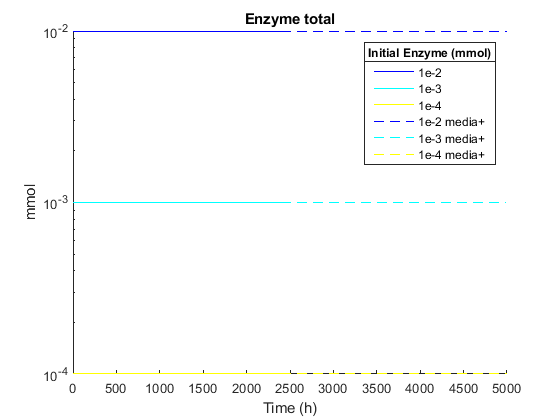

colors = [jet(3); jet(3)];
linetype = {'-' '-' '-' '--' '--' '--'};
dat6ndb = vertcat(dat6nd(1:3,:),dat6nd_extramedia);
nrows = 6;

figure();
hold on;
for i = 1:nrows
    plot(dat6ndb.t{i},dat6ndb.enz_total{i},linetype{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend({'1e-2' '1e-3' '1e-4' '1e-2 media+' '1e-3 media+' '1e-4 media+'});
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

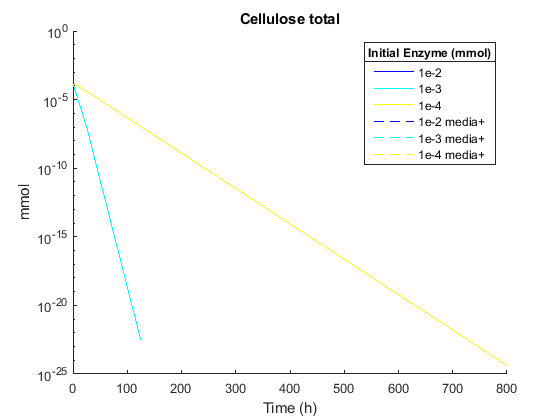


figure();
hold on;
for i = 1:nrows
    plot(dat6ndb.t{i},dat6ndb.cellulose_total{i},linetype{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend({'1e-2' '1e-3' '1e-4' '1e-2 media+' '1e-3 media+' '1e-4 media+'});
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

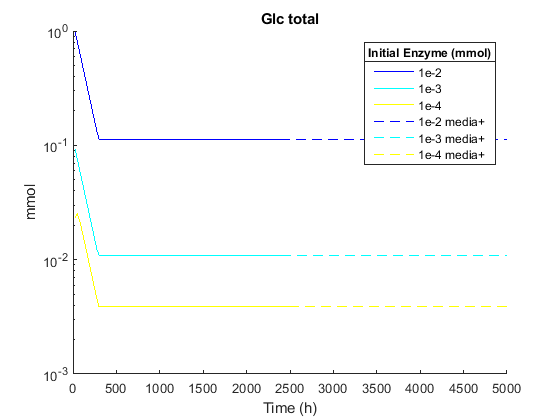


figure();
hold on;
for i = 1:nrows
    plot(dat6ndb.t{i},dat6ndb.glc_total{i},linetype{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend({'1e-2' '1e-3' '1e-4' '1e-2 media+' '1e-3 media+' '1e-4 media+'});
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

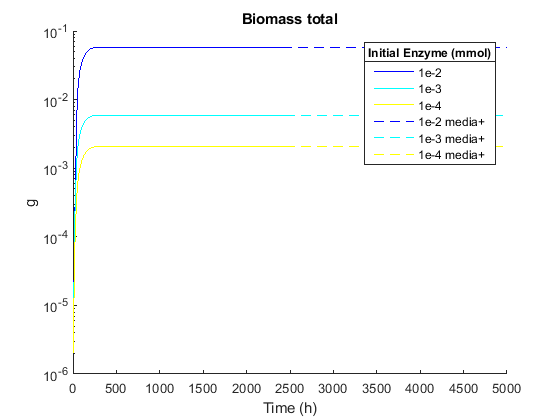


figure();
hold on;
for i = 1:nrows
    plot(dat6ndb.t{i},dat6ndb.producer_total{i} + dat6ndb.cheater_total{i},linetype{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend({'1e-2' '1e-3' '1e-4' '1e-2 media+' '1e-3 media+' '1e-4 media+'});
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('g');

hold off;

Conclusion: Limited media is not the cause for different stopping points.